# `.....Spike Analyzer.....`

- *Developed by Mohamed Hisham*

- *updated May 12, 2023.*

- *Contact: Mohamed.mousa@wright.edu*

`Version 6.3`

This version measures:

- RMP

- Action potential Height

- Max rising slope

- Average rising slope

- Max falling slope

- Average falling slope

- Action potential half-amplitude width

- Action potential width

- AP time to peak ( AP start time to the peak time)

- AHP depth (RMP noise corrected) AHP depth - half of the estimated noise

- AHP depth (AHP noise corrected)

- Estimate noise based on the standard deviation of the RMP

- AHP noise ( based on the noise around the mAHP trough)

- AHP time to rise ( AHP start to AHP trough)

- AHP half-amp decay ( time from AHP trough to AHP half-amp point)

- AHP 2/3 Amp decay ( time between spike start to 2/3 AHP decay point)

- AHP 1/2 Duration ( time between the half-amp point on the rising phase and decaying phase)

- AHP Duration (time from the AHP start to the AHP end)

- fAHP estimation ( AP end voltage)

**Features: Interpolation, filteration, Robust AP start detection, Overlay AHP trace, save filtered and raw side by side, exponential fitting added

saving all data side by side (4.5), bug fixed to use the derivative to get the starting point, Manually selection for the AP start point (5.0), manual selection for AHP peak (5.9), **new wavelet denoization (6.0), **html export fixed (6.2)

__________________________________________________________

# `Main Script`

## 1) Clear workspace first

 
clear
clc

- Please clear the output manually "right-click on the output, and select ***Clear All output***"  or

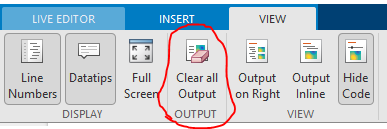

#### parameters

global SecDerProminace pointindex est_noise RMP extractedProperties interpolationFactor peakH ManualStart AHPdepthManual filename
interpolationFactor = 4; % interpolationFactor of 2 doubles the precision to accurate detection of the AP half-width
peakH               = -40;%(-40) % Minimum peak height to detect the spikes
SecDerProminace     = 0.1;
ManualStart         = false; % make it 1 for manual selection, 0 for Automatic
AHPdepthManual      = false;
% filename            = enterFilename()
init();
 

**Update some parameters during run**

ManualStart         = false; % make it 1 for manual selection, 0 for Automatic
AHPdepthManual      = false;

**1.b) Auto Gen Filename**

spikeType = "ADSpike";
 
[~,filename,~]  = fileparts(pwd); % extract filename from folder - assumes folder has date and cell info
filename        = strcat(filename,"(",spikeType,")");               % creates filename based on folder and suffix
disp('Created automatic filename:');

Created automatic filename:


disp(filename);

Action Potential measurements(ADSpike)


## **2) Open file**

open .mat and .txt files.

- prepare the file to include only the spike, other depolarizations artifacts may cause errors.

User selected E:\Work\NERD lab Code\Action Potential measurements\ADspike7-10-cell2_chrissy.mat
The file was opened successfully in the workspace


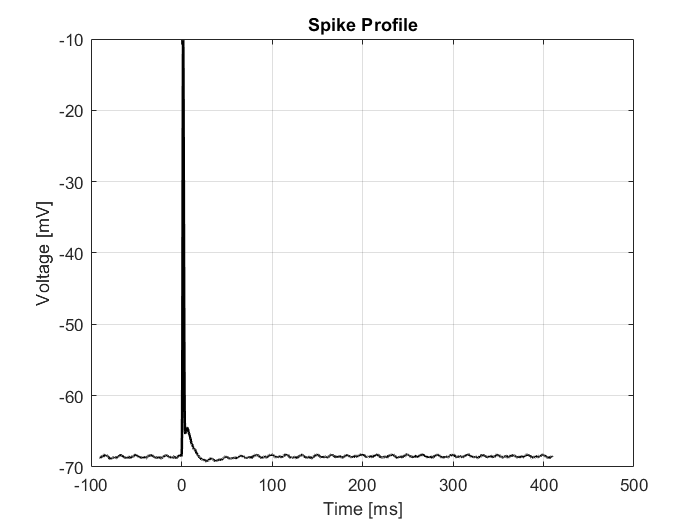

 
[Vm0, time0] = open_file();

## **3) Detect points:**

- **Analyze spike, plot points and show the measurements table**

Noise estimated to be 0.1395 mV


***Noise is estimated based on the std of the selected part***
The Reference RMP is -68.58 mV
AP start -> 2nd Drv based


T = 19×2 table
              propertiesName              extractedProperties
    __________________________________    ___________________

    {'RMP (mV)'                      }          -68.582      
    {'AP Height (mV)'                }           58.426      
    {'Max Rise slope (V/s)'          }            60.12      
    {'Avg Rise slope (V/s)'          }           27.004      
    {'Max Falling Slope (V/s)'       }           -45.13      
    {'Avg Falling slope (V/s)'       }          -23.479      
    {'half Amp width (ms)'           }            1.625      
    {'AP width (ms)'                 }              4.4      
    {'AP time to peak'               }              2.1      
    {'AHP depth{RMP corrected} (mV)' }           0.5513      
    {'AHP depth {AHP corrected} (mV)'}          0.59934      
    {'RMP noise estimation (mV)'     }          0.13948      
    {'AHP noise estimation'          }         0

Data saved in Action Potential measurements(ADSpike)_AP_trace.csv.


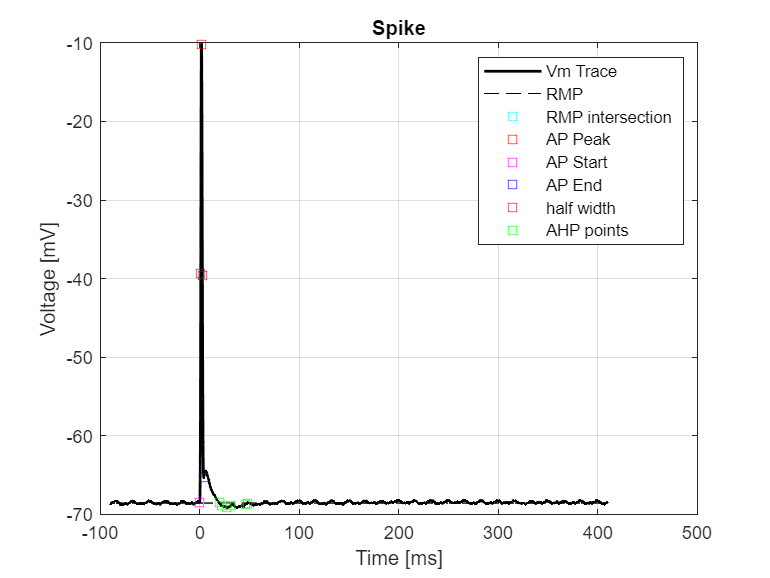

Spike picture saved as Action Potential measurements(ADSpike)_AP_trace.csv.


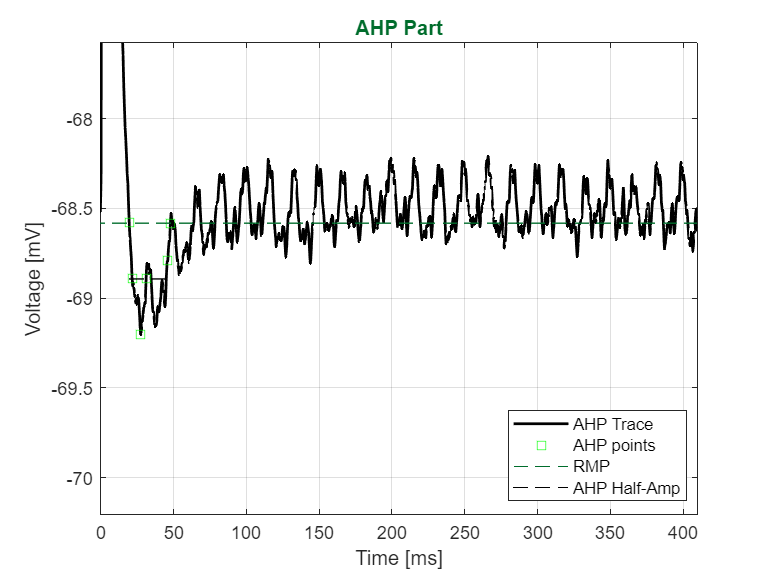

AHP picture saved as Action Potential measurements(ADSpike)_Spike.


 
Spikeproperties = AnalyzeSpike(Vm0, time0);

## **4) Save Results to Excel sheet**

 
savetoXlsx(1,Spikeproperties);

## 5) Save the current results to html

- *Code is hided automatically now (new)*

 
saveHTML();

# `....Smoothing, and exponential fitting for noisy traces....`

### 1.A) Generate and plot smoothed Data

Sf =0.03;
[Vmf,timef] = plotSmooth(Vm0,time0,Sf);%0.1 default smoothingFactor
 

### 1.B) Desnoise data using *Wavelet (new)*

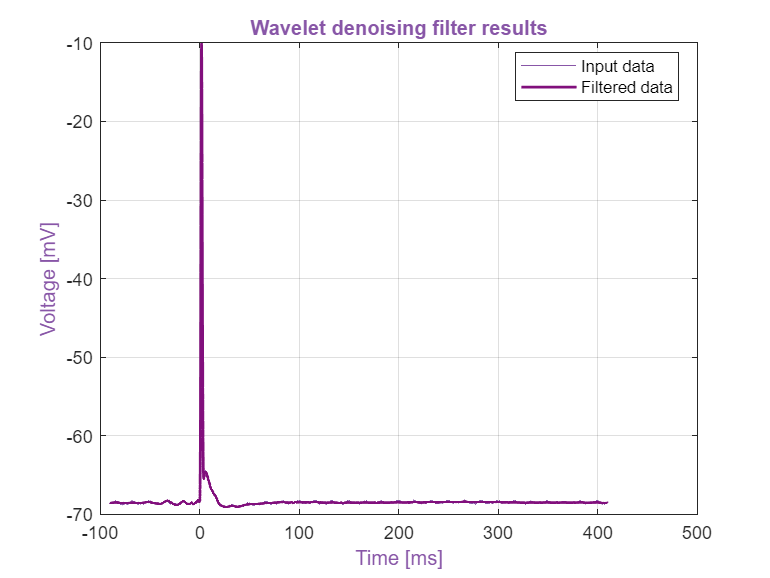

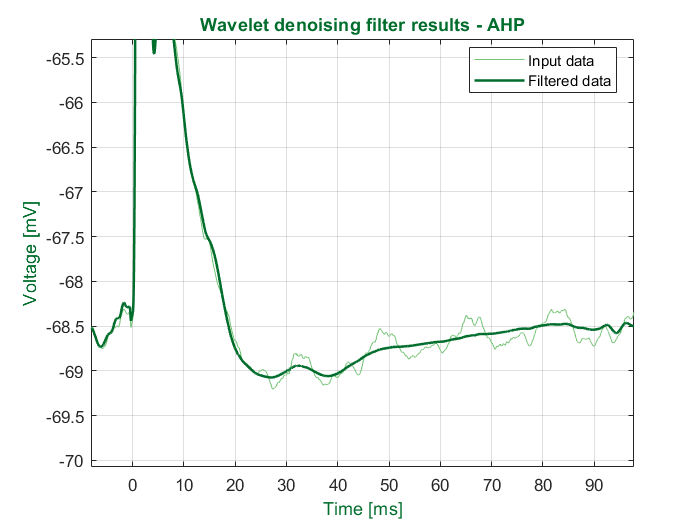

 
opt =1; % opt 1 is usually the best
Vmf = waveletDenoising(Vm0,time0,opt);

timef = time0;VmW = Vmf;

`Smooth wavelet output`

Sf =0.03;
[Vmf,timef] = plotSmooth(VmW,time0,Sf);%0.1 default smoothingFactor
 

### 2) Analyze filtered Data

Noise estimated to be 0.0877 mV
***Noise is estimated based on the std of the selected part***
The Reference RMP is -68.54 mV
AP start -> 2nd Drv based


T = 19×2 table
              propertiesName              extractedProperties
    __________________________________    ___________________

    {'RMP (mV)'                      }           -68.541     
    {'AP Height (mV)'                }            58.381     
    {'Max Rise slope (V/s)'          }            60.152     
    {'Avg Rise slope (V/s)'          }            26.968     
    {'Max Falling Slope (V/s)'       }           -45.205     
    {'Avg Falling slope (V/s)'       }           -23.528     
    {'half Amp width (ms)'           }            1.6125     
    {'AP width (ms)'                 }               4.4     
    {'AP time to peak'               }               2.1     
    {'AHP depth{RMP corrected} (mV)' }           0.48858     
    {'AHP depth {AHP corrected} (mV)'}            0.5306     
    {'RMP noise estimation (mV)'     }          0.087678     
    {'AHP noise estimation'          }         0

Data saved in Action Potential measurements(ADSpike)_AP_trace(1).csv.


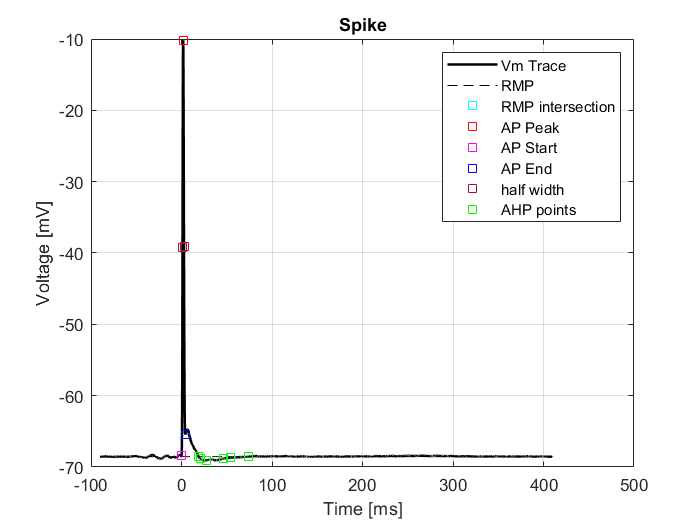

Spike picture saved as Action Potential measurements(ADSpike)_AP_trace(1).csv.


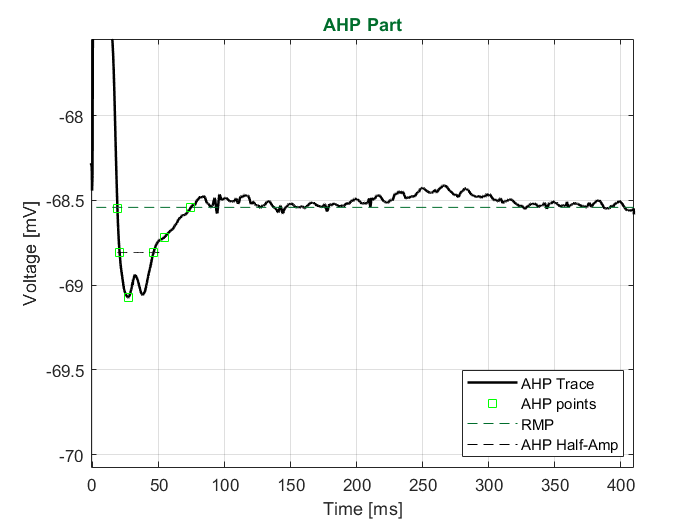

AHP picture saved as Action Potential measurements(ADSpike)_Spike(1).png.


 
%interpolationFactor = 1  % must be 1 , it may work now with the default
ESpikeproperties = [];
FSpikeproperties = AnalyzeSpike(Vmf,timef,0);

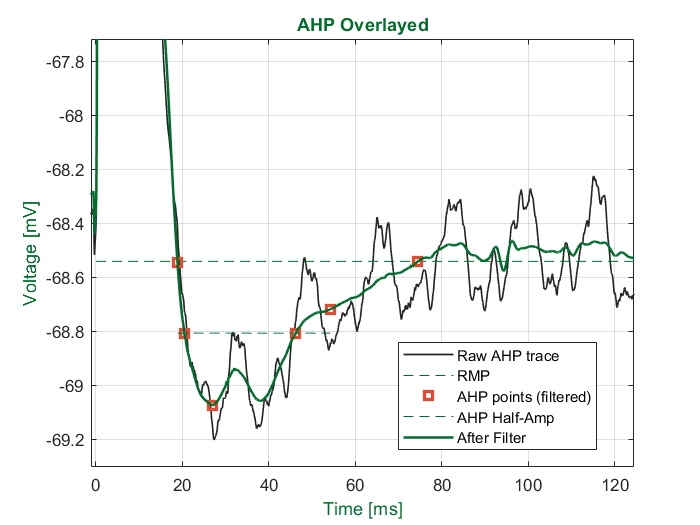

OverLayAHP(Vm0,time0,Vmf, timef)

### 2.a) Analyze the Filtered Data with exponential fit

use the last filtered vector, which is generated from 1A or 1B

 
interpolationFactor = 1; % must be 1
ESpikeproperties = AnalyzeSpike(Vmf,timef,1);

### 2.b) Just PLOT the AHP exponential fit.

 
[Vmf2,old] = AHPfit(Vmf,timef,1);

### 3) Overlay filtered AHP over the raw one + point

 
OverLayAHP(Vm0,time0,Vmf, timef)

# `.....Saving AP features to CSV.....`

#### 4.a) Save ALL spike properties

- raw data properties is saved side by side with the filtered data. [ Raw , filtered, AHP_extFit]

 
savetoXlsx(1,[Spikeproperties FSpikeproperties ESpikeproperties]);

#### 4.b) Display both raw, filtered and exp. fitted data properties side by side here

 
savetoXlsx(0,[Spikeproperties FSpikeproperties ESpikeproperties]);

`html interactive figures`

[https://plotly.com/matlab/getting-started/](https://plotly.com/matlab/getting-started/)

- open the figure you want to convert to interactive html

f = fig2plotly(gcf, 'open', false);
addtheme(f, 'simple_white');
response = plotlyoffline(f);
web(response, '-browser');

`functions...............................................(do not run from here)`

function properties = AnalyzeSpike(Vm,time,expFit)
    if(nargin == 2)
        expFit = 0;
    end

    global pointindex est_noise RMP extractedProperties
    est_noise = -1; extractedProperties = []; pointindex = [];
    %% get RMP potential and estimate noise
    [est_noise, RMP] = getRMP_noise(Vm,time);
    if(est_noise == -1)
        error('We have error in calculating the RMP, try again')
        return
    end
    %% get start, peak and end point of the spike
    [Vm,time] =  SpikePoints(Vm,time); % this function change the length of the vector
    Vm        =  AHP_Analyze(Vm, time,expFit);
    savetoXlsx(0,extractedProperties);
    properties = extractedProperties; % back to be saved in the workspace
    saveAP([time Vm]);
end


`open function`

function [Vmv, time] = open_file()
%browse for files:
    [file,path,fileType] = uigetfile({'*.mat';'*.txt'},'select .mat file or .txt file only');
    if isequal(file,0)
        disp('User selected Cancel');
    else
        disp(['User selected ', fullfile(path,file)]);
    end
    if(fileType == 1)% if matlab
        Vm = load(fullfile(path,file),'-mat');
        fields = fieldnames(Vm);
        Vm     = getfield(Vm,fields{1});
        Vmv = Vm.values; time = Vm.times*1000;
    elseif(fileType == 2) % if txt
        Vm    = dlmread(fullfile(path,file),'\t',1,0);
        Vmv = Vm(:,2); time = Vm(:,1)*1000;
    end
    disp('The file was opened successfully in the workspace');
    clear fields path file file
    
    % clipping out first sample
    Vmv(1) = [];
    time(1)= [];
    
%     Interpolations make problems here, to the
%     dervative calculations if activated here, activate it better after
%     calculating of the derivative.
    %% plotting
    figure(9)
    plot(time,Vmv,'k','linewidth',1.5), grid on
    xlabel("Time [ms]"),ylabel("Voltage [mV]"), title("Spike Profile");

end
%%---------------------------------------------------------------------------------------------

- Spike three defining points ( peak, start, end)

function [Vmv, time]=SpikePoints(Vmv, time)
%% this function detect the spike, including its starting and end points

    global SecDerProminace extractedProperties RMP pointindex interpolationFactor peakH
    
    %detect peak of spike
    [pks,locs] = findpeaks(Vmv,'MinPeakProminence',SecDerProminace*30,'MinPeakHeight',peakH);
    figure(10),hold on
    plot(time(locs),Vmv(locs),'rs','DisplayName','AP Peak');hold off;
    
    % get the first derivative
    Vmdiff = diff(Vmv);
    delta_T    = time(21)-time(20);% time difference in middle point
    % get the second derivative
    Vmdiff2 = diff(Vmdiff);
    
    [pksE2,locsE2] = findpeaks(-Vmdiff(locs:end),'MinPeakProminence',SecDerProminace*4);
    locsE2 = locsE2+locs-1; % make sure the end detected is after the peak
    % detect the first peak in the second derivative to get B1 index (IS rise peak)
    [pksB1,locsB1] = findpeaks(Vmdiff2,'MinPeakProminence',SecDerProminace,'NPeaks',2);
    %detecting B2 point ( Early start of AP)
    B2Array = [-1]; % empty 
    for j = locsB1:-1:2
        if(Vmdiff2(j) >= Vmdiff2(j-1) && Vmdiff2(j)<0 )
            B2Array(1,1)     = j;
            B2Array(1,2)     = Vmdiff2(j);
            break;
        end
    end
    % detecting E1 point ( vally of the f_AHP)
    for j = locsE2(1)+1:length(Vmdiff)-1
        if(Vmdiff(j) > Vmdiff(j-1) && (Vmdiff(j) > Vmdiff(j+1) || Vmdiff(j) > 0) && (Vmdiff(j) > -1))
            E1Array(1,1)     = j;
            E1Array(1,2)     = Vmdiff(j);
            break;
        end
    end
    

Decide on the AP start

    APstart = getSpikefirstPt(Vmv,B2Array(1,1),locs, time); 
    
    %% increasing the vector length to get fine points better
    [time, Vmv] = linearInterpolation(time, Vmv,interpolationFactor);

    %% the return
    pointindex = [pointindex;locs; APstart(:,1); E1Array(:,1)]; % [RMP], peak, start, end
    pointindex = correctIndex(pointindex,interpolationFactor);
    
    %% extracting properties (using old int
    maxRisingSlope = max(Vmdiff(APstart(:,1):E1Array(:,1))/delta_T ); % V/s
    maxfallingSlope= min(Vmdiff(APstart(:,1):E1Array(:,1))/delta_T );
    avgRisingSlope = mean(Vmdiff(APstart(:,1):locs)/delta_T );
    avgfallSlope   = mean(Vmdiff(locs:E1Array(:,1))/delta_T );
    %% find halfwidth
    APHeight = pks-RMP;
    halfAmp  = (pks+RMP)/2;
    
    searchL  = pointindex(3):pointindex(2);
    searchR  = pointindex(2):pointindex(4);
    
    lind =  abs( Vmv( searchL )-halfAmp ) == min( abs( Vmv(searchL)-halfAmp )) ;
    rind =  abs( Vmv( searchR )-halfAmp ) == min( abs( Vmv(searchR)-halfAmp )) ;
    
    lind = searchL(lind);
    rind = searchR(rind);
    
    hSpikeW  = time(int64(rind(1)))-time( int64(lind(1)));
    APwidth  = time(pointindex(4))- time(pointindex(3) );
    time2peak= time(pointindex(2))-time(pointindex(3));
    
    %%output
    extractedProperties = [RMP;APHeight;maxRisingSlope;avgRisingSlope;maxfallingSlope;avgfallSlope; hSpikeW;APwidth;time2peak];
    
    figure(10), hold on
    plot(time(pointindex(3)),Vmv(pointindex(3)),'ms','DisplayName','AP Start');
    plot(time(pointindex(4)),Vmv(pointindex(4)),'bs','DisplayName','AP End');
    plot(time([lind;rind]),Vmv([lind;rind]),'s','DisplayName','half width');
    hold off


end

**RMP and noise**

%%------------------------------------------------------
function [est_noise, RMP] = getRMP_noise(Vvector,time)
    global pointindex peakH SecDerProminace
    est_noise = -1;

switch nargin
    case 2
        figure(105)
        plot(time,Vvector,'k','linewidth',1), grid on, xlabel("Time [ms]"),ylabel("Voltage [mV]"),
        title('>>Choose the Area of the RMP (ONLY TWO POINTS), ENTER to submit, DELETE or SPACE  to remove');
        
        [xi,yi] = getpts(figure(105));
        if(length(xi) == 2)
            if(xi(1) < xi(2))
                leftx  = xi(1);
                rightx = xi(2);
            else
                leftx = xi(2);
                rightx= xi(1);
            end
            close(105);
            % find index
            leftind  = find( abs(time-leftx) == min( abs(time-leftx)) );
            rightind = find( abs(time-rightx) == min( abs(time-rightx)) );
            RMP      = mean(Vvector(leftind:rightind));
            est_noise= std(Vvector(leftind:rightind));
            disp(['Noise estimated to be ' num2str(round(est_noise,4)) ' mV']);
            if(est_noise > 0.12)
                warning("Noise is too High!, try to use the filtered method")
            end
            disp(['***Noise is estimated based on the std of the selected part***']);
            %end of case 2
        else
            warning('you should choose only two points, please try again')
            return
        end
end
disp(['The Reference RMP is ' num2str(round(RMP,2)) ' mV']);

[pks,locs] = findpeaks(Vvector,'MinPeakProminence',SecDerProminace*30,'MinPeakHeight',peakH);

figure(10), clf,
plot(time,Vvector,'k','linewidth',1.5,'DisplayName','Vm Trace'), grid on
xlabel("Time [ms]"),ylabel("Voltage [mV]"), title("Spike"), legend('-DynamicLegend');
hold on
plot(time, ones(length(time),1)*RMP,'--k','DisplayName','RMP');
hold off
% get intersection point between RMP and Vm ( search from the peak to
% the end
interSecPoint = getPoint(Vvector,RMP,locs(1),length(Vvector),0);
pointindex(1)    = [interSecPoint]; % AHP start point

if(length(interSecPoint) ~= 0)
    figure(10), hold on
    plot(time(interSecPoint), Vvector(interSecPoint),'cs','DisplayName','RMP intersection');
    hold off
end

end

### **AHP functions:**

%% ------------------- AHP start ----------------------
function Vm = AHP_Analyze(Vm, time,expFit)
global pointindex est_noise RMP extractedProperties interpolationFactor AHPdepthManual
Endind = length(Vm);

PointsVoltage = Vm(pointindex);
if( PointsVoltage(4) < PointsVoltage(1) )
    warning(['The End of the Action Potential is below the RMP'])
    disp(['You must select the AHP starting point manually'])
    warning(['look at the command window for prompt'])
    x = input('Hey,to proceed to the manual extraction of the AHP start point TYPE 1:');
    if(x==1)
        AHP_sind = manualStartAHP(Vm,time);
        pointindex = [ pointindex; AHP_sind];
    else
        return
    end
else
    AHP_sind   = pointindex(1); % the RMP
    pointindex = [ pointindex; AHP_sind];
end

Exponential fit replacment

if(expFit == 1)
    [Vm,beforeFitdata] = AHPfit(Vm,time,0);
end

Analyzing AHP! , and extracting properties

if(~AHPdepthManual)
    [AHPvallyV AHPvallyI]  = min(Vm(AHP_sind:end));
    AHPvallyI              = AHPvallyI + AHP_sind-1;
else
    AHPvallyI = manualPeakAHP(Vm,time);
    AHPvallyV = Vm(AHPvallyI);

end
        %% AHP localized noise
AHPnoise               = std(Vm( (AHPvallyI-interpolationFactor*20):(AHPvallyI+interpolationFactor*20)));
        % AHP properties
halfdecay              = getPoint(Vm,(AHPvallyV+RMP)/2, AHPvallyI, Endind, 1);% half decay index
halfdecaydur           = time(halfdecay)-time(AHPvallyI);
ahp2_3Ind              = getPoint(Vm,(RMP-(RMP-AHPvallyV)/3),AHPvallyI, Endind, 1);                  
time2peak              = time(AHPvallyI)-time(AHP_sind);
ahp2_3dur              = time(ahp2_3Ind)-time(pointindex(3));
% AHP 1/2 duration
halfRiseInd            = getPoint(Vm,(AHPvallyV+RMP)/2,AHP_sind, AHPvallyI, 0); % half rising index
AHPhalfDur             = time(halfdecay)-time(halfRiseInd);
AHPdurInd              = getPoint(Vm,RMP,halfdecay,Endind,1); % AHP duration

if(isempty(AHPdurInd))
    warning(['Could not find end to the AHP, Trace MAY NOT BE LONG ENOUGH']);
    AHPdurInd =  find(abs( Vm( halfdecay:end )- RMP ) == min( abs( Vm(halfdecay:end)-RMP )));
    AHPdurInd =  halfdecay + AHPdurInd -1;
    disp(['Calculating the AHP duration based on the closest point to the RMP..']);
%   AHPdurInd = length(Vm)-1;
end
AHPduration            = time(AHPdurInd)-time(AHP_sind); % plot the half amplitude dash line.
%% aggregating the points
inds                   = [AHP_sind;halfRiseInd;AHPvallyI;halfdecay;ahp2_3Ind;AHPdurInd];
lengthplot             = length(time(AHP_sind:ahp2_3Ind));

%% Aggregating the APH points to be saved
pointindex = [pointindex;halfRiseInd;AHPvallyI;halfdecay;ahp2_3Ind;AHPdurInd];

figure(10),hold on % AP figure....
plot(time(inds),Vm(inds),'gs','DisplayName','AHP points');

figure(11) % AHP figure....
plot(time,Vm,'k','linewidth',1.5,'DisplayName','AHP Trace'), hold on
plot(time(inds),Vm(inds),'gs','DisplayName','AHP points');
plot(time, ones(length(time),1)*RMP,'LineStyle','--','color', "#006d2c",'DisplayName','RMP');
plot(time(AHP_sind:ahp2_3Ind),ones(lengthplot,1)*((AHPvallyV+RMP)/2),'--k','DisplayName','AHP Half-Amp');
if(expFit==1)
    plot(time(AHPvallyI:end),beforeFitdata(AHPvallyI:end),"--r",'DisplayName','Replaced AHP trace')
end
grid on, ylim([min(Vm)-1 Vm(pointindex(1))+1]), legend('Location', 'Best');
if((time(AHP_sind) - time(1)) > 50) 
    xlim([time(AHP_sind)-20 time(end)])
end
xlabel("Time [ms]"),ylabel("Voltage [mV]"), title("AHP Part",'color', "#006d2c");
hold off;

%% saving data
extractedProperties = [extractedProperties;(RMP-AHPvallyV-est_noise/2);(RMP-AHPvallyV-AHPnoise/2);...
    est_noise;AHPnoise;time2peak;halfdecaydur;ahp2_3dur;AHPhalfDur;AHPduration;Vm(pointindex(4))];


%% Validate AHP results
    if(ahp2_3dur>AHPduration )
        warning(['AHP 2/3 decay is longer than AHP full duration!!, these AHP results may not be VALID' newline 'please filter the data'])
%         f = msgbox('AHP 2/3 decay is longer than AHP full duration!!, these AHP results may not be VALID',"invalid results","warn","replace");
%         f.WindowStyle = 'docked'
    end


end

get AHP starting point manually.

%% manual AHP start point-------------------------------------------------------
function ind = manualStartAHP(Vm,time)
    global pointindex RMP
    figure(106)
    plot(time,Vm,'k','linewidth',1,'DisplayName','AHP trace'), grid on,hold on
    plot(time, ones(length(time),1)*RMP,'--k','DisplayName','RMP');
    xlabel("Time [ms]"),ylabel("Voltage [mV]"), legend('Location', 'Best')
    title('>> Define the AHP starting point, ENTER to submit, DELETE or SPACE to remove point');
    ylim([min(Vm)-0.5 Vm(pointindex(1))+0.5]);
    
    [xi,yi] = getpts(figure(106));
    % find index
    ind  = find( abs(time-xi(1)) == min( abs(time-xi(1))  ) );
    close(106)
    figure(10), hold on
    plot(time(ind), Vm(ind),'ms','DisplayName','AHP start');
    hold off
end

get AHP starting point manually.

%% manual AHP start point-------------------------------------------------------
function ind = manualPeakAHP(Vm,time)
    global pointindex RMP
    [AHPvallyV AHPvallyI]  = min(Vm(pointindex(1):end));
    AHPvallyI              = AHPvallyI + pointindex(1)-1;

    figure(106)
    plot(time,Vm,'k','linewidth',1,'DisplayName','AHP trace'), grid on,hold on
    plot(time, ones(length(time),1)*RMP,'--k','DisplayName','RMP');
    plot(time, ones(length(time),1)*AHPvallyV,'--','color','#478778','DisplayName','AHP peak suggested line');

    xlabel("Time [ms]"),ylabel("Voltage [mV]"), legend('Location', 'Best')
    title('>> Define the AHP Peak point, ENTER to submit, DELETE or SPACE to remove point');
    ylim([min(Vm)-0.5 Vm(pointindex(1))+0.5]);
    
    [xi,yi] = getpts(figure(106));
    % find index
    ind  = find( abs(time-xi(1)) == min( abs(time-xi(1))  ) );
    close(106)
    figure(10), hold on
    plot(time(ind), Vm(ind),'ms','color','#478778','DisplayName','AHP Peak');
    hold off
end

#### Saving function..........................

function savetoXlsx(saving,extractedProperties)
    global filename

propertiesName = {'RMP (mV)';'AP Height (mV)';'Max Rise slope (V/s)' ...
    ;'Avg Rise slope (V/s)';'Max Falling Slope (V/s)';'Avg Falling slope (V/s)'...
    ;'half Amp width (ms)';'AP width (ms)';'AP time to peak';'AHP depth{RMP corrected} (mV)';...
    'AHP depth {AHP corrected} (mV)';'RMP noise estimation (mV)';'AHP noise estimation';...
    'AHP time to peak (ms)';'AHP half decay (ms)';'AHP 2/3 decay (ms)';...
    'AHP 1/2 duration (ms)';'AHP duration (ms)';'fAHP potential (mV)'};

lnT= length(propertiesName);
ln = length(extractedProperties);
if(ln < lnT)
    warning('Table not complete, uncalculated properties are placed with "0" ');
    extractedProperties = [extractedProperties; zeros(lnT-ln,1)];
    
end
T = table(propertiesName,extractedProperties);

if(saving == 1)
%     filename = input('Enter the file name:','s');
    filename0 = strcat(filename,'_AP_features.csv');
    writetable(T,filename0,'WriteVariableNames',false);
    disp("Data saved in "+filename0+".");
else % printing
    T = T
end

end

**Saving the Figures data:**

function saveAP(APdata)
    global filename
    i      = 1;

    T = array2table(APdata);
    T.Properties.VariableNames = {'Time (ms)','Voltage (mV)'};
    filename1 = strcat(filename,'_AP_trace.csv');
    %% saving the AP figure
    filename2 = strcat(filename,'_Spike');
    filename3 = strcat(filename,'_AHP');
    
    while( isfile(filename1) )
        filename1 = strcat(filename,"_AP_trace("+num2str(i)+").csv");
        filename2 = strcat(filename,"_Spike("+num2str(i)+").png");
        filename3 = strcat(filename,"_AHP("+num2str(i)+").png");
        i         = i+1;
    end
    if(i > 3)
        warning('more than Three spikes were saved, kindly check if you have dublicates')
    end
    
    writetable(T,filename1,'WriteVariableNames',true);
    disp("Data saved in "+filename1+".");
    
    %savefig(figure(10),filename);
    print(figure(10),'-dpng','-r600',filename2);
    disp("Spike picture saved as "+filename1+".");
    
    %% save AHP
    print(figure(11),'-dpng','-r600',filename3);
    disp("AHP picture saved as "+filename2+".");

end


**Filename prombt**

function filename = enterFilename()
    warning("Enter the cell code name in the command window as requested");
    filename = input('Enter the cell code to rename the files:','s');
end

**Supporting functions**, search, and refute

function Findex = getSpikefirstPt(Vmv,Drev2pt,peakind,time)
    global RMP ManualStart
    
    % get RMP intersection, 
    RMPind = getPoint(Vmv,RMP,peakind,1,1);
    
%     Vmv([RMPind Drev2pt])
%     disp([RMPind Drev2pt])
    
    if(ManualStart == 1 )
        
        figure(90)
        plot(time,Vmv,'k','linewidth',1.5), grid on
        xlabel("Time [ms]"),ylabel("Voltage [mV]"), title(">> Pick the AP start point. (ONLY ONE point)");
        [xi,yi] = getpts(figure(90));
        ind  = find( abs(time-xi(1)) == min( abs(time-xi(1))  ) );
        close(90)
        Findex = ind;
        disp("AP start was selected Manually")
        
    elseif(Drev2pt > RMPind)
        Findex = Drev2pt;
        disp("AP start -> 2nd Drv based") 
    else
        Findex = RMPind;
        disp("AP start -> RMP based")
    end
    

end
%% general find point function-----------------------------------------
function ind = getPoint(Vm,value, start, End, pos_slope)
    
    if(start < End)
        step = 1;
    else
        step = -1;
    end

    caughtpoints = [];
    ind          = [];
    
    if(pos_slope == 1)
        for(j=start+step:step:End-step)
            if( (Vm(j-1) < value) && (Vm(j+1) > value) )
                caughtpoints = [caughtpoints, j];
            end
        end
    else
        for(j=start+step:step:End-step)
            if( (Vm(j-1) > value) && (Vm(j+1) < value) )
                caughtpoints = [caughtpoints, j];
            end
        end
    end
    ln = length(caughtpoints);
    
    if(ln >=2 )
        caughtpoints = refutePoints(caughtpoints,value,Vm);
        ln = length(caughtpoints);
    end
    
    if(ln >=2 )
        % for dubugging
       % disp(['Caught more than one point(',num2str(ln),')']);
       % disp(caughtpoints);
    end
    
    if(ln > 0)
        ind = caughtpoints(1);
    else
        warning('No points found to match');
        return
    end
end
%%-----------------------------refute points to remove the repeated ones
%%
function cleanVec = refutePoints(vector,val,Vm)

    cleanVec = vector;
    
    for i = 1:1:length(vector)-1
        if( (vector(i)-vector(i+1)) == -1 )
            ind = leastErrorPoint(Vm(vector(i+1)),Vm(vector(i)),val);
%             cleanVec        = [cleanVec, vector(i+ind)];
            cleanVec(i+ind) = -1;
        end
    end
    deleteind = cleanVec==-1;
    cleanVec(deleteind) = [];
    
    vector = cleanVec;
    
     for i = 1:1:length(vector)-1
        if( (vector(i)-vector(i+1)) == 1 )
            ind = leastErrorPoint(Vm(vector(i+1)),Vm(vector(i)),val);
%             cleanVec        = [cleanVec, vector(i+ind)];
            cleanVec(i+ind) = -1;
        end
     end
     
    deleteind = cleanVec==-1;
    cleanVec(deleteind) = [];
end
%% closest point
function ind = leastErrorPoint(pt1,pt2,val)
    error1 = pt1 - val;
    error2 = pt2 - val;
    if(abs(error1) <= abs(error2) )
        ind = 0;
    else
        ind = 1;
    end
end

**Interpolation factor,**

- change resFactor to change the vector length and fill the new vector with interpolated data

- the function is useful to easly detect the half AP width by increasing the sampling rate artificially

function [time, Vmv] = linearInterpolation(time, Vmv,resFactor )
% By Default the function double the resolution
% use only integars
    switch nargin
        case 2
            resFactor = 2;      
    end
    if(resFactor == 1)
        return
        
    else
        newlength = (  (length(time)-1)*resFactor )  +1;
        newTime   = linspace(time(1),time(end),newlength)';
        newVmv    = interp1(time,Vmv,newTime);
        time      = newTime; Vmv = newVmv; clear newTime newVmv 
    end

end

indexing correction function

function [outArray] = correctIndex(index,resFactor)

    outArray = ((index-1)*resFactor) + 1;
end

smoothing function

function [VmS timeS] = plotSmooth(Vm,time,smoothingFactor)
    % Smooth input data
    VmS     = smoothdata(Vm,'movmean','SmoothingFactor',smoothingFactor);
    timeS   = smoothdata(time,'movmean','SmoothingFactor',smoothingFactor);
    
    % Visualize results
    figure()
    plot(time,Vm,'Color',[109 185 226]/255,'DisplayName','Input data')
    xlabel("Time [ms]",'Color',[0 114 189]/255),ylabel("Voltage [mV]",'Color',[0 114 189]/255)
    hold on
    plot(timeS,VmS,'Color',[0 114 189]/255,'LineWidth',1.5,...
        'DisplayName','Smoothed data'),grid on, title("Average filter results",'Color',[0 114 189]/255 )
    hold off
    legend('Location', 'Best')
end

iniating

function init()
    global SecDerProminace pointindex est_noise RMP extractedProperties
    
    pointindex      = [];est_noise  = [];
    RMP        = []; extractedProperties = []; 
    
end

**AHP fitting with exponential fitting**

function [Vm,oldVm] = AHPfit(Vm,time, plotflag)
    global pointindex RMP
    
    if(isempty(pointindex))
        AHP_sind = manualStartAHP(Vm,time);
    else
        AHP_sind = pointindex(5);
    end


    % AHP vally point
    [AHPvallyV AHPvallyI]  = min(Vm(AHP_sind:end));
    AHPvallyI              = AHPvallyI + AHP_sind-1;
    
    fitIndex = AHPvallyI:length(time);
    x = time(fitIndex);
    y = Vm(fitIndex);
    
    % exponential fitting
    f = fit(x,y,'exp2'); %'StartPoint',[1,2]
    fy1 = feval(f,x); % fitted data
    
    oldVm = Vm;
    
    %replace orignal vector with the fitted data
    Vm(fitIndex) = fy1;
    
    
    if(plotflag == 1)
        figure()
        plot(time,oldVm,'k','linewidth',1,'DisplayName','AHP trace'), grid on,hold on
        if(~isempty(pointindex))
            plot(time, ones(length(time),1)*RMP,'LineStyle','--','color', "#006d2c",'DisplayName','RMP');
        end
        xlabel("Time [ms]"),ylabel("Voltage [mV]"), legend('Location', 'Best')
        title('>> AHP exponential fit');
        ylim([min(Vm)-0.1 Vm(pointindex(1))+0.2]);
        
        hold on
        plot(x,fy1,'-r','linewidth',2.5,'DisplayName','Exponential fit')
        hold off
    end
 
end


**AHP before and after wavelet filter**

#### OverLay AHP

function OverLayAHP(Vm,time,Vmf,timef)
    global pointindex RMP interpolationFactor

    % interpolate the vector similar to the pointIndex
    [time, Vm] = linearInterpolation(time, Vm,interpolationFactor);
    [timef, Vmf] = linearInterpolation(timef, Vmf,interpolationFactor);

    if(isempty(pointindex))
        AHP_sind = manualStartAHP(Vm,time);
    else
        % if using the raw vector
%         inds     = round((pointindex(5:end)-1)/interpolationFactor,0) +1;
%         pInd     = round((pointindex(1)-1)/interpolationFactor,0) +1 ; %RMP
%         AHP_sind = inds(1);
        % if interpolating the vector
        inds     = pointindex(5:end);
        pInd     = pointindex(1); %RMP
        AHP_sind = inds(1);
    end
        
        figure()
        plot(time,Vm,'color',"#252525",'linewidth',1,'DisplayName','Raw AHP trace'), grid on,hold on
        if(~isempty(pointindex))
            plot(time, ones(length(time),1)*RMP,'LineStyle','--','color', "#006d2c",'DisplayName','RMP');
        end
        plot(timef(inds),Vmf(inds),'gs','DisplayName','AHP points (filtered)','Color',"#e34a33","LineWidth",2,...
            'MarkerSize',6);
        plot(timef(inds(1):inds(5)),ones(inds(5)-inds(1)+1,1)*(Vmf(inds(2))),'LineStyle','--','color','#006d2c','DisplayName','AHP Half-Amp');
        xlabel("Time [ms]",'Color','#006d2c'),ylabel("Voltage [mV]",'Color','#006d2c'), legend('Location', 'Best')
        title("AHP Overlayed",'Color','#006d2c');
        ylim([min(Vm)-0.1 Vm(pInd)+0.7]);
        if((time(AHP_sind) - time(1)) > 50) 
            xlim([time(AHP_sind)-20 time(inds(end))+50])
        end
        
        plot(timef,Vmf,'Color','#006d2c','linewidth',1.5,'DisplayName','After Filter')
        hold off

 
end

save Html file

function saveHTML()
    global filename
    filename1 = strcat(pwd,'/',filename,'_Spike.html');
    filename1 = convertStringsToChars(filename1);
    mlxloc = matlab.desktop.editor.getActiveFilename;
    if(isempty(mlxloc))
        disp("cannot find the script path, please enter the script full path in the 'command window'")
        disp('*** you can get it by right click on the script, and copy the script full path to the clipboard ***')
        mlxloc = input('Enter the script full path to save:','s');
    end
%     matlab.internal.liveeditor.openAndConvert(mlxloc,filename1,'HideCode', true);
    export(mlxloc,filename1,Format="html",OpenExportedFile=true,HideCode=true)
    disp("HTML file saved as "+filename1+".");
end



Wavelet Desoising method


function Vmw = waveletDenoising(Vmv,time,opt)
    global pointindex RMP interpolationFactor
    ind = round((pointindex-1)/interpolationFactor + 1,0);  % reset the index

    Wopt = strcat("sym",num2str(9-opt));
    Vmw = wdenoise(Vmv,11,Wavelet=Wopt,DenoisingMethod="Bayes",NoiseEstimate="LevelDependent",...
        thresholdRule = "Mean");

    % Visualize results
    figure()
    plot(time,Vmv,'Color','#8856a7','DisplayName','Input data')
    xlabel("Time [ms]",'Color','#8856a7'),ylabel("Voltage [mV]",'Color','#8856a7')
    hold on
    plot(time,Vmw,'Color','#810f7c','LineWidth',1.5,...
        'DisplayName','Filtered data'),grid on
    hold off, title("Wavelet denoising filter results",'Color','#8856a7')
    legend('Location', 'Best')

    m = mean(Vmw); minn = min(Vmw);
    % Visualize AHP results
    figure()
        plot(time,Vmv,'Color','#74c476','DisplayName','Input data')
    xlabel("Time [ms]",'Color','#006d2c'),ylabel("Voltage [mV]",'Color','#006d2c')
    hold on
    plot(time,Vmw,'Color','#006d2c','LineWidth',1.5,...
        'DisplayName','Filtered data'),grid on
    hold off, title("Wavelet denoising filter results - AHP",'Color','#006d2c')
    legend('Location', 'Best')
    ylim([minn-1 m+3]);
    if(~isempty(ind))
        xlim([time(ind(2))-10 time(ind(end))+50]);
    end

end
